# **Norma IEEE-754**

El año 1985, Institute for Electrical and Electronic Engineers (IEEE) va publicar el informe Binary Floating Point Arithmetic Standard 754 − 1985, en el que se especifican normas para representar numeros en punto flotante con precisión simple doble y formatos de precision extendidos. El año 2008 fue publicada el IEE Std 754-2008. 

La norma IEEE-754 define:

- Formatos aritméticos: conjuntos de datos de punto flotante binarios y decimales, que consisten en números finitos, includios los ceros con singo, y los números desnormalizados, infinitos y valores especiales "no numéricos" (Nan).

- Formatos de intercambio: codificaciones (cadenas de bits) que se pueden utilizar para intercambiar datos de punto flotante de forma eficiente y compacta.

- Reglas de redondeo: propiedades que deben satisfacer al redondear los numeros.

- Operaciones aritmeticas.

- Indicaciones de excepciones: overflow, underflow, divisiones por cero...

# **Formatos aritméticos**

## **Single and Double Precision:**

### **Single Precision**

la represenatción en punto flotante de simple precisión ocupa 1 word(32 digitos), asignando: 1 bit para el signo del numero real, 8 bits para el exponente y 23 bits para la mantisa. 

Un nombre real x en simple precisión se reprensenta de la siguiente manera:

              

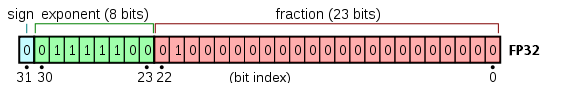

Donde **s** es el valor del signo. **c** es el valor del exponente (con signo).   el valor de la mantissa. 

Los valores de los exponentes con todo 0's o todo 1's, estan reservados. 

### **Denormal number (Single Precision)**

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los numeros normalizados, es decir, s es el valor del signo y    el valor de la mantissa. El valor del exponente no se utiliza.

### **Double Precision**

la representación en punto flotante con doble precision ocupa 2 words(64 digitos), asignando: 1 bit para el signo del numero real, 11 bits para el exponente y 52 bits para la mantisa.

Un nombre real x en simple precisión se reprensenta de la siguiente manera:

            

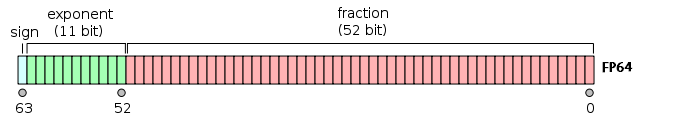

Donde **s** es el valor del del signe. **c** es el valor del exponente (con signo).  el valor de la mantisa.

Los valores de los exponentes con todo 0's o todo 1's, estan reservados. 

### **Denormal number (Double Precision)**

Si el exponente es 0 y la mantisa diferente de 0. 

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los numeros normalizados, es decir, s es el valor del signo y    el valor de la mantissa. El valor del exponente no se utiliza.

### Inf

Si el exponente es todos 1 y la mantisa es 0 representa a los numeros infinitos. En caso de que el signo sea 0 respresenta el +infinito.En caso de que el signo sea 1 representa -infinito.

### **Nan(Not-A-Number)**

Si el exponente es todos 1 y la mantisa es diferente de 0 representa Nan(Not-A-Number).  Esto se utiliza para expresar un resultado imposible de calcular (raíces negativas, division por cero)...

### **Zero**

Si el exponente es todos 0 y la mantisa 0 representa al 0. En caso de que el signo sea 0 representa el +0. En casi de que el signo sea 1 representa -0.

Fenomenos producidos por la artimetica

# **Fenomenos producidos por la aritmetica **

**roundoff error**

**underflow**

**overflow**

# **Resumen Norma IEEE-754**

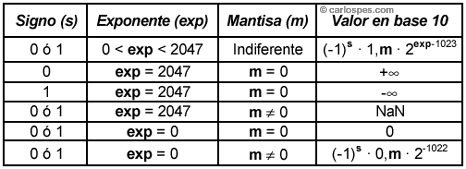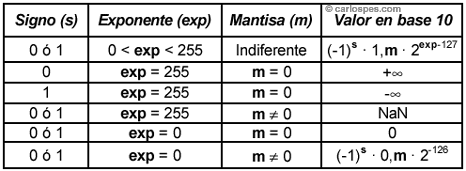

**Biografia:**

[https://es.wikipedia.org/wiki/IEEE_coma_flotante](https://es.wikipedia.org/wiki/IEEE_coma_flotante)

[https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/](https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/)

[https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/](https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/)

# Exercici2

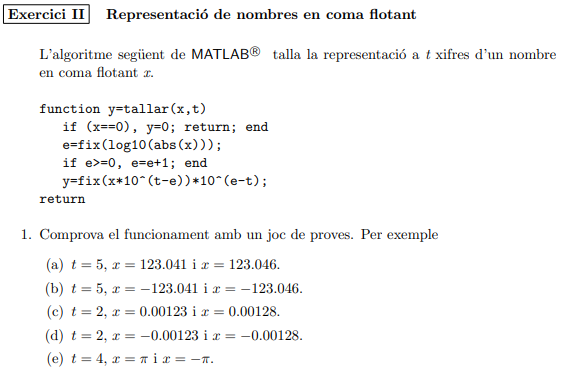

**a)**

format compact
format long
t = 5;
x = 123.051;
ya = tallar(x,t)

ya =      1.230500000000000e+02

x = 123.046;
ya = tallar(x,t)

ya =      1.230400000000000e+02

**b)**

t = 5;
x = -123.041;
yb = tallar(x,t)

yb =     -1.230400000000000e+02

x = -123.046;
yb = tallar(x,t)

yb =     -1.230400000000000e+02

**c)**

t = 2;
x = 0.00123;
yc = tallar(x,t)

yc =    0.001200000000000

x = 0.00128;
yc = tallar(x,t)

yc =    0.001200000000000

**d)**

t = 2;
x = -0.00123;
yd = tallar(x,t)

yd =   -0.001200000000000

x = -0.00128;
yd = tallar(x,t)

yd =   -0.001200000000000

**e)**

t = 4;
x = pi;
ye = tallar(x,t)

ye =    3.141000000000000

x = -pi;
ye = tallar(x,t)

ye =   -3.141000000000000

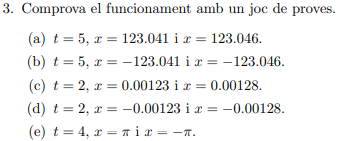

t = 5;
x = 123.051;
ya = redondear(x,t)

ya =      1.230500000000000e+02

x = 123.046;
ya = redondear(x,t)

ya =      1.230500000000000e+02

**b)**

t = 5;
x = -123.041;
yb = redondear(x,t)

yb =     -1.230400000000000e+02

x = -123.046;
yb = redondear(x,t)

yb =     -1.230500000000000e+02

**c)**

t = 2;
x = 0.00123;
yc = redondear(x,t)

yc =    0.001200000000000

x = 0.00128;
yc = redondear(x,t)

yc =    0.001300000000000

**d)**

t = 2;
x = -0.00123;
yd = redondear(x,t)

yd =   -0.001200000000000

x = -0.00128;
yd = redondear(x,t)

yd =   -0.001300000000000

**e)**

t = 4;
x = pi;
ye = redondear(x,t)

ye =    3.142000000000000

x = -pi;
ye = redondear(x,t)

ye =   -3.142000000000000

# Exercici 3

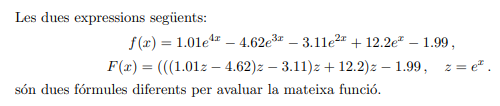

e = exp(1);
f_original = @(x) 1.01*e^(4*x)-4.62*e^(3*x)-3.11*e^(2*x)+12.2*e^x-1.99

f_original = function_handle with value:
    @(x)1.01*e^(4*x)-4.62*e^(3*x)-3.11*e^(2*x)+12.2*e^x-1.99



f = @(x,t)redondear(1.01*redondear(e^(4*x),t),t)-redondear(4.62*redondear(e^(3*x),t),t)-redondear(3.11*redondear(e^(2*x),t),t)+redondear(12.2*(e^x),t)-1.99;

F = @(x,t)redondear(redondear(redondear(redondear(redondear((redondear(redondear(redondear(1.01*redondear(e^x,t),t)-4.62,t)*redondear(e^x,t),t)-3.11),t)*redondear(e^x,t),t)+12.2,t)*redondear(e^x,t),t)-1.99,t)

F = function_handle with value:
    @(x,t)redondear(redondear(redondear(redondear(redondear((redondear(redondear(redondear(1.01*redondear(e^x,t),t)-4.62,t)*redondear(e^x,t),t)-3.11),t)*redondear(e^x,t),t)+12.2,t)*redondear(e^x,t),t)-1.99,t)


f1 = f(1.53,3)

f1 = -6.8900

F1 = F(1.53,3)

F1 = -7.0700

f1_original = f_original(1.53)

f1_original = -7.6079

f2 = f(0.925,4)

f2 = -24.2500

F2 = F(0.925,4)

F2 = -24.2600

f2_original = f_original(0.925)

f2_original = -24.2489

errorf1 = abs(f1_original-f1)/abs(f1_original)*100

errorf1 = 9.4359

errorF1 = abs(f1_original-F1)/abs(f1_original)*100

errorF1 = 7.0699


errorf2 = abs(f2_original-f2)/abs(f2_original)*100

errorf2 = 0.0044

errorF2 = abs(f2_original-F2)/abs(f2_original)*100

errorF2 = 0.0457

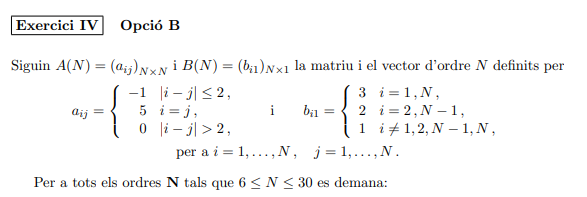

N = 6;
A = zeros(N);
for i = 1:N
    for j = 1:N
        if abs(i-j) <= 2 && i ~= j
            A(i,j) = -1;
        elseif   i == j
            A(i,j) = 5;
        else
            A(i,j) = 2;
        end
    end
end
A

A =      5    -1    -1     2     2     2
    -1     5    -1    -1     2     2
    -1    -1     5    -1    -1     2
     2    -1    -1     5    -1    -1
     2     2    -1    -1     5    -1
     2     2     2    -1    -1     5


b = ones(1,N)*3;
b(2) = 2;
b(N-1) = 2;
b(3:N-2) = 1;
b = b'

b =      3
     2
     1
     1
     2
     3


x = A\b

x =     0.3333
    0.3333
    0.3333
    0.3333
    0.3333
    0.3333


%Eliminacio Gaussiana



function y=tallar(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = fix(x*10^(t-e))*10^(e-t);
    return
end
function y=redondear(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = round(x*10^(t-e))*10^(e-t);
    return
end